# Actividad 1 (velovidades angulares y lineales)

Para esta actividad obtendremos el valor de la velocidad linal y agular de la siguiente configuracion de un robot: 

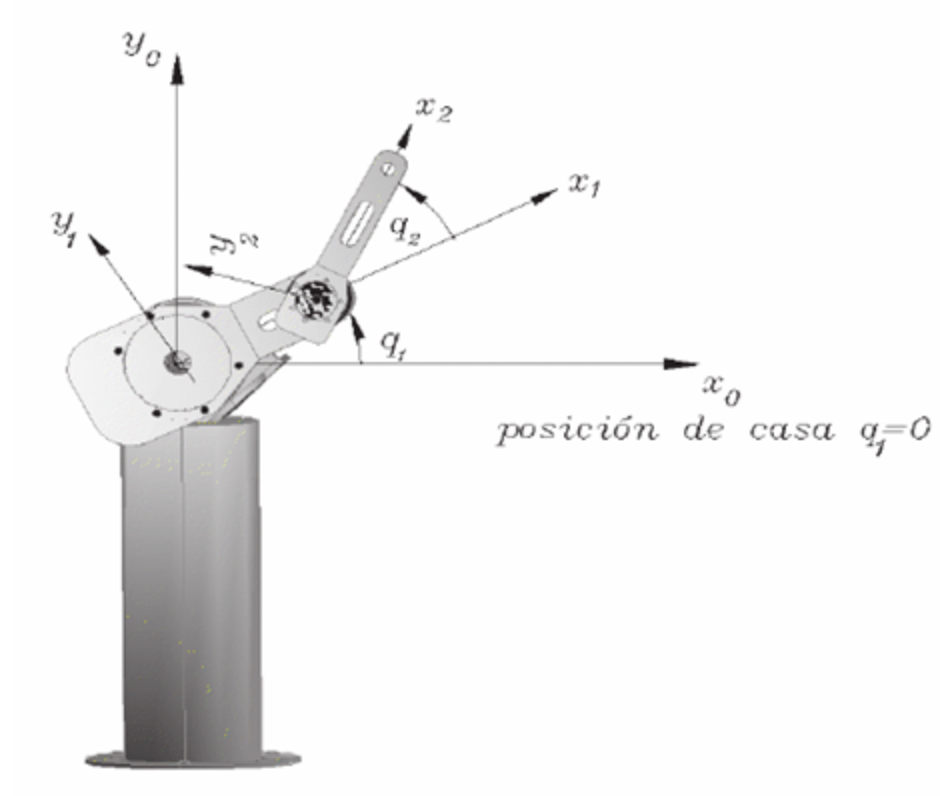

Primerolimpiaremos nuestro worckspace

clear all;
close all;
clc;

Declaramos como variables simbolicas th1, l1, th2, l2

syms th1(t) l1 th2(t) l2 t;

Se declara la configuracion del robot, declarando un variable RP donde 0 es para la junta rotacional y 1 para la junta prismatica

RP=[0 0];

Se crea el primer vector de las coordenadas generalizadas.

Q=[th1 th2];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty(Q);

(th1(t), th2(t))



Creamos el vector de velocidades generalizadas

Qp = diff(Q,t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty(Qp);

/  d          d        \
| -- th1(t), -- th2(t) |
\ dt         dt        /



Se inicializan los numeros de grado de libertad del robot.

GDL = size(RP,2);

Obtenemos el vector de translación de la articulación 1 y 2 respecto a 0.

P(:,:,1) = [l1*cos(th1);
            l1*sin(th1);
                0];
P(:,:,2) = [l1*cos(th1)+l2*cos(th1+th2);
            l1*sin(th1)+l2*sin(th1+th2);
                0];

Igualmente obtenemos la matriz de rotación de la junta 1 y 2 respecto a 0

R(:,:,1)=[cos(th1) -sin(th1) 0;
          sin(th1) cos(th1)  0;
          0 0 1];

R(:,:,2)=[cos(th2) -sin(th2) 0;
          sin(th2) cos(th2)  0;
          0 0 1];

Creamos un vector de ceros e inicializamos las matrices de transformacion homogenea locales y globales

Vector_Zeros = zeros(1,3);
%Local
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Global
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);

/ - l1 sin(th1(t)) - l1 sin(2 th1(t)) 2 \
|                                       |
|                                2      |
| l1 (cos(th1(t)) + 4 cos(th1(t))  - 2) |
|                                       |
\                   0                   /



Inicializamos los vectores de posicion y las matrices de rotación vistos desde el marco de referencia inicial

PO(:,:,GDL) = P(:,:,GDL);
RO(:,:,GDL) = R(:,:,GDL);

Creamos un ciclo for que clculara RO Y PO dependiendo en cuantos grados de libertad espesificamos en GDL

for i = 1 : GDL
    i_str = num2str(i);
    %locales
    disp(strcat('Matriz de transformacion local A', i_str));
    A(:,:,i) = simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));
    %globales
    try
        T(:,:,i)= T(:,:,i-1)*A(:,:,1);%Caso específico cuando i=1 nos marcaría error en try
    catch
        T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de tranformacion global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,1));
    %obtenemos la matriz de rotacion "RO" y el vector de tranlacion PO de
    %la matriz de transformacion homogenea global T(:,:,GDL)
    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);
    pretty(RO(:,:,i));
    pretty(PO(:,:,i));
end

Calculamos el Jacobiano lineal de forma diferencial

disp('Jacobiano lineal obtenido de forma diferencial');

Derivadas parciales de x respecto a th1

Jv11= functionalDerivative(PO(1,1,GDL), th1);

Jacobiano lineal obtenido de forma analitica


Derivadas parciales de y respecto a th1

Jv21= functionalDerivative(PO(2,1,GDL), th1);

/    -l1 (sin(th1(t)) + sin(2 th1(t))),       -l1 sin(2 th1(t))   \
|                                                                 |
|                                       2                  2      |
| l1 cos(th1(t)) - l1 + 2 l1 cos(th1(t)) , 2 l1 cos(th1(t))  - l1 |
|                                                                 |
\                    0,                               0           /



Derivadas parciales de y respecto a th1 y th2

Jv31= functionalDerivative(PO(3,1,GDL), th1);

Jacobiano angular obtenido de forma analitica


Obtenemos la matriz del jacobiano lineal 

jv_d = simplify([Jv11; ...

/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /



                 Jv21; ...
                 Jv31]);

velocidad lineal obtenida mediante el jacobiano lineal


pretty(jv_d);

Inicializamos las variables del jacobiano lineal y angular calculado de forma analitica

%inicializamos jacobianos analiticos (lineal y angular)

/             _________                         _________          \
|              d                                 d                 |
|        - l1 -- th1(t) (sin(th1(t)) + #1) - l1 -- th2(t) #1       |
|             dt                                dt                 |
|                                                                  |
|    _________                            _________                |
|     d                                    d                       |
| l1 -- th1(t) (cos(th1(t)) + 2 #2 - 1) - -- th2(t) (l1 - 2 l1 #2) |
|    dt                                   dt                       |
|                                                                  |
\                                 0                                /

where

   #1 == sin(2 th1(t))

                    2
   #2 == cos(th1(t))




Jv_a(:,GDL)=PO(:,:,GDL);

velocidad angular obtenida mediante el jacobiano lineal


Jw_a(:,GDL)=PO(:,:,GDL);

Creamos un ciclo for que calculara nuestros jacobianos linieales y angulares dependiendo  si la articulacion es rotacinal o prismatica:

for k= 1:GDL

/           0           \
|                       |
|           0           |
|                       |
| _________   _________ |
|  d           d        |
| -- th1(t) + -- th2(t) |
\ dt          dt        /



    if ((RP(k)==0|(RP(k)==1)))%casos: articulacion rotacional y prismatica
        %para las articulaciones rotacinales
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%
            Jw_a(:,k)= [0,0,1];
        end
    else
        %para las articulaciones prismaticas
        try
            Jv_a(:,k)=RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
        Jw_a(:,k)=[0,0,0];
    end
end

Calculamos el Jacoviano Lineal y Angular de forma analitica

Jv_a = simplify (Jv_a);
Jw_a = simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analitica');
pretty(Jv_a);
disp('Jacobiano angular obtenido de forma analitica');
pretty(Jw_a);

Y por ultimo se calcula la velocidad Linear y Anguular utilizando el respectivo Jacobiano para cada caso.

disp('velocidad lineal obtenida mediante el jacobiano lineal');
V = simplify(Jv_a*Qp');
pretty(V);
disp('velocidad angular obtenida mediante el jacobiano angular');
W = simplify(Jw_a*Qp');
pretty(W);

## Resultados:

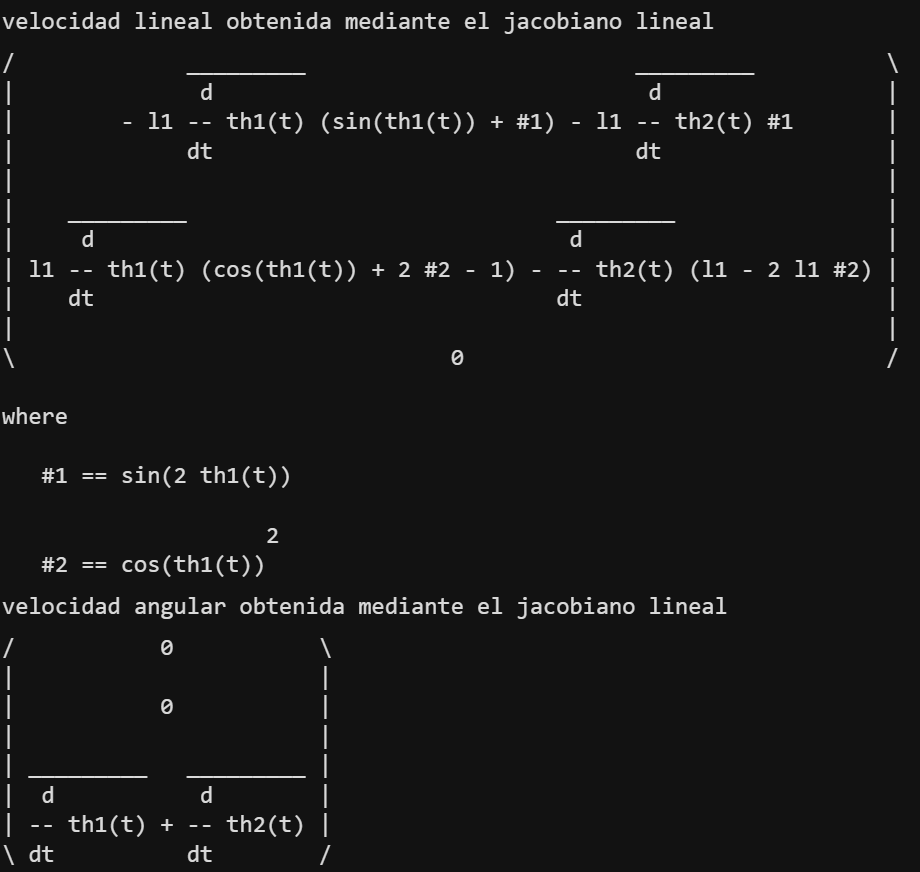

Para la velocidad lineal podemos ver como es que la matriz esta bien modelada ya que tienen toda la libertada para moverce en ese sentido. Sin enbargo podemos ver como en la velocidad angular tenemos 0 en z ya que nuestro robot no puede moverse en ese angulo.